PMR3523 - Controle Moderno

Entrega 2 - Posicionamento Dinâmico de Embarcações

Ângelo Bianco Yanagita

Diôgo Lopes Cavalcante

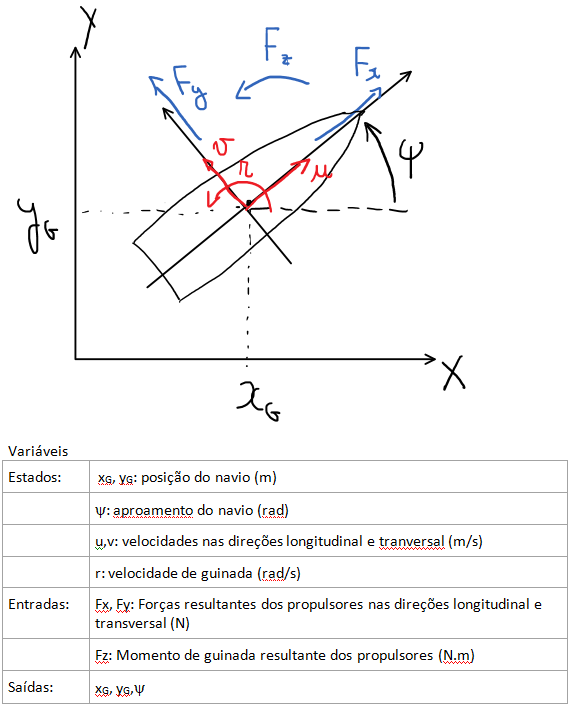

Equações do sistema:

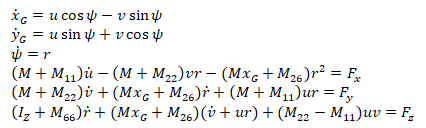

As variáveis de estado, entrada e saída são as seguintes:


$$\begin{array}{l}x={\left\lbrack \begin{array}{cccccc}x_g  & y_g  & \psi 
\; & u & v & r\end{array}\right\rbrack }^T \\u={\left\lbrack \begin{array}{ccc}F_x  
& F_y  & F_z \end{array}\right\rbrack }^T \\y={\left\lbrack \begin{array}{ccc}x_g  
& y_g  & \psi \;\end{array}\right\rbrack }^T \end{array}$$


Declaração das simbólicas a serem usadas

syms xg yg psi u v r Fx Fy Fz m m11 m22 m26 m66 izz
syms xg_dot yg_dot psi_dot u_dot v_dot r_dot


Definição dos membros direitos da equação de cada estado

eq1 = u*cos(psi) - v*sin(psi);
eq2 = u*sin(psi) + v*cos(psi);
eq3 = r;
eq4 = (Fx + (m*xg + m26)*r^2 + (m + m22)*v*r)/(m+m11);
eq5 = (Fy -(m*xg + m26)*r_dot - (m + m11)*u*r)/(m+m22);
eq6 = (Fz - (m*xg + m26)*(v_dot + u*r) - (m22 - m11)*u*v)/(izz + m66);

Definição das equações de saída:

eq7 = xg;
eq8 = yg;
eq9 = psi;

Linearização de acordo com as seguintes condições:

e entradas nos esforços propulsores todas nulas.


taylor_xg_dot = taylor(eq1, [u, v, psi], 0 , 'Order', 2)

$$taylor\_xg\_dot = u$$


taylor_yg_dot = taylor(eq2, [u, v, psi], 0 , 'Order', 2)

$$taylor\_yg\_dot = v$$


taylor_psi_dot = taylor(eq3, r , 0 , 'Order', 2)

$$taylor\_psi\_dot = r$$


taylor_u_dot = taylor(eq4, [xg, r, v, Fx], 0 , 'Order', 2)

$$taylor\_u\_dot = \frac{\mathrm{Fx}}{m+m_{11}}$$


taylor_v_dot = taylor(eq5, [xg, r_dot, u, r, Fy], 0 , 'Order', 2)

$$taylor\_v\_dot = \frac{\mathrm{Fy}}{m+m_{22}}-\frac{m_{26}\,r_{\mathrm{dot}}}{m+m_{22}}$$


taylor_r_dot = taylor(eq6, [xg, v_dot, u, r, v, Fz], 0 , 'Order', 2)

$$taylor\_r\_dot = \frac{\mathrm{Fz}}{\mathrm{izz}+m_{66}}-\frac{m_{26}\,v_{\mathrm{dot}}}{\mathrm{izz}+m_{66}}$$

feitas as expansões de taylor de cada membro direito, têm-se as equações linearizadas de estado

lin_xg_dot = taylor_xg_dot

$$lin\_xg\_dot = u$$


lin_yg_dot = taylor_yg_dot

$$lin\_yg\_dot = v$$


lin_psi_dot = taylor_psi_dot

$$lin\_psi\_dot = r$$


lin_u_dot = taylor_u_dot

$$lin\_u\_dot = \frac{\mathrm{Fx}}{m+m_{11}}$$


lin_v_dot = v_dot == taylor_v_dot;

lin_r_dot = r_dot == taylor_r_dot;

Isolando as derivadas de v e r:

[lin_v_dot,lin_r_dot]=solve([lin_v_dot,lin_r_dot],[v_dot,r_dot])

$$lin\_v\_dot = \frac{\mathrm{Fy}\,\mathrm{izz}+\mathrm{Fy}\,m_{66}-\mathrm{Fz}\,m_{26}}{-{m_{26}}^{2}+\mathrm{izz}\,m+\mathrm{izz}\,m_{22}+m\,m_{66}+m_{22}\,m_{66}}$$

$$lin\_r\_dot = \frac{\mathrm{Fz}\,m-\mathrm{Fy}\,m_{26}+\mathrm{Fz}\,m_{22}}{-{m_{26}}^{2}+\mathrm{izz}\,m+\mathrm{izz}\,m_{22}+m\,m_{66}+m_{22}\,m_{66}}$$

Criação das Matrizes:

syms d

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];
 
B = [0             0                 0; 
     0             0                 0;
     0             0                 0;
     1/(m+m11)     0                 0;
     0             (izz+m66)/d       -m26/d;
     0             -m26/d            (m+m22)/d];

C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];

D = 0;

display(A)

A =      0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


display(B)

$$B = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ \frac{1}{m+m_{11}} & 0 & 0\\ 0 & \frac{\mathrm{izz}+m_{66}}{d} & -\frac{m_{26}}{d}\\ 0 & -\frac{m_{26}}{d} & \frac{m+m_{22}}{d} \end{array}\right)$$

display(C)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


display(D)

D = 0

Usando os valores numéricos do enunciado:

m = 7240e3;
izz = 2750e6;
m11 = 640e3;
m22 = 6400e3;
m66 = 1560e6;
m26 = 7900e3;

d=-m26^2+izz*m+izz*m22+m*m66+m22*m66;

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];
 
B = [0             0                 0; 
     0             0                 0;
     0             0                 0;
     1/(m+m11)     0                 0;
     0             (izz+m66)/d       -m26/d;
     0             -m26/d            (m+m22)/d];

C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 0 0 0 0];

D = 0;

display(A)

A =      0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


display(B)

B =    1.0e-06 *

         0         0         0
         0         0         0
         0         0         0
    0.1269         0         0
         0    0.0734   -0.0001
         0   -0.0001    0.0002


display(C)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


display(D)

D = 0

Definindo tempo de simulação:

t = 0:0.001:10;
i = 1 % contador para os gráficos

i = 1

Definindo matriz de vasculhamento:

single_G=[0.05 0.1 0.25];
double_G=[0 0.05;
          0 0.1;
          0 0.25;
          0.05 0;
          0.05 0.05;
          0.05 0.1;
          0.05 0.25;
          0.1 0;
          0.1 0.05;
          0.1 0.1;
          0.1 0.25;
          0.25 0;
          0.25 0.05;
          0.25 0.1;
          0.25 0.25];

Gerando gráficos comparativos para cada entrada atuando sozinha com 100% do esforço de controle:

Fx:

(1) $F_x =2\ldotp 5*{10}^{5\;} \;N;F_{y\;} =0\;;M_z =0$

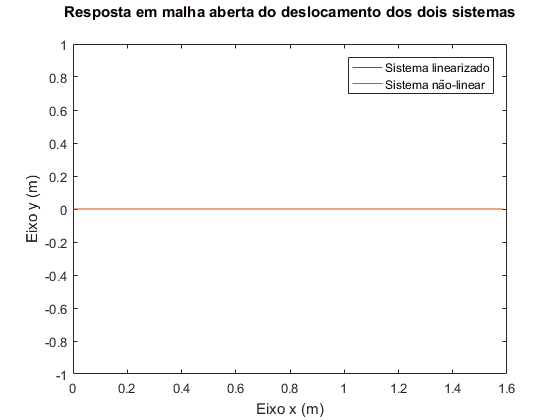

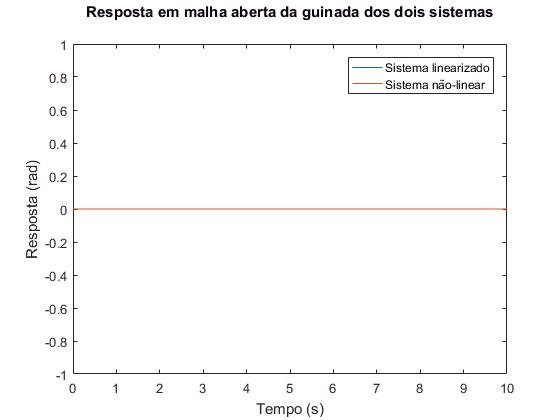

fx = 2.5e5;
fy = 0;
mz = 0;

[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i);

Fy:

(2) $F_x =0\;;F_{y\;} =2\ldotp 5*{10}^5 \;\;N;M_z =0$

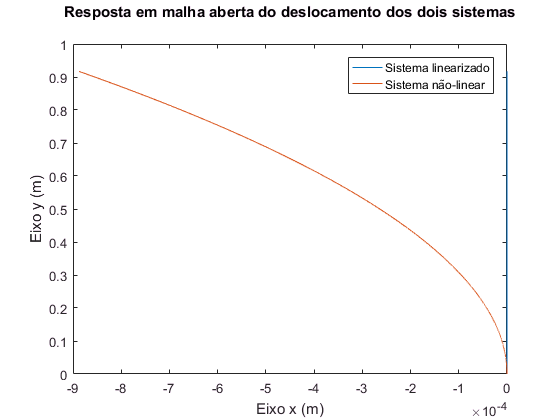

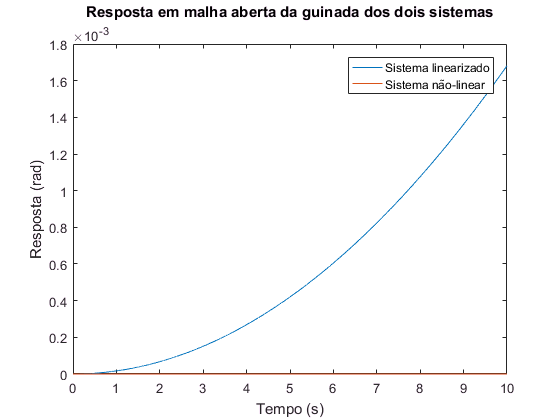

fx = 0;
fy = 2.5e5;
mz = 0;

[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i);

Fz:

(3) $F_x =0  \;;F_{y\;} =0 \;;M_z =1*{10}^7 \;N.m$

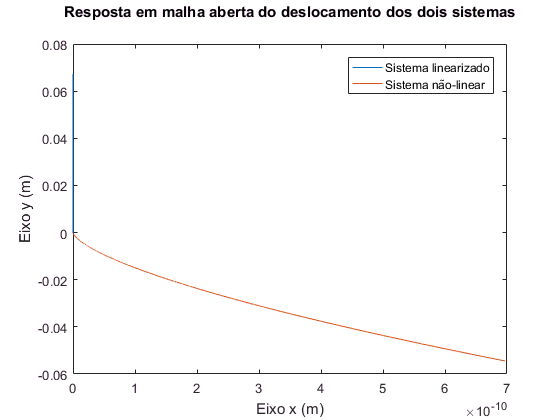

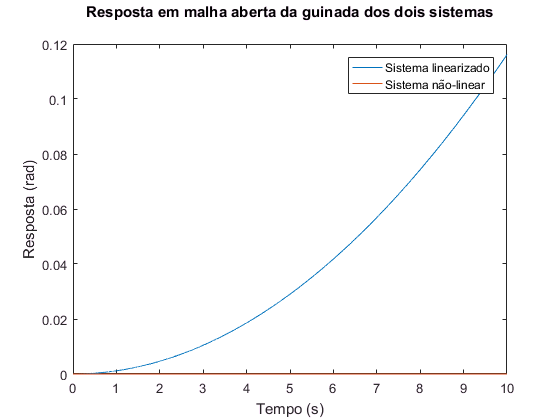

fx = 0;
fy = 0;
mz = 1e7;

[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i);

Testando agora outras combinações:

(4) $F_x=2.5 \cdot 10^5 N \; ; F_y= 2.5 \cdot 10^5 N \; ;M_z=0$

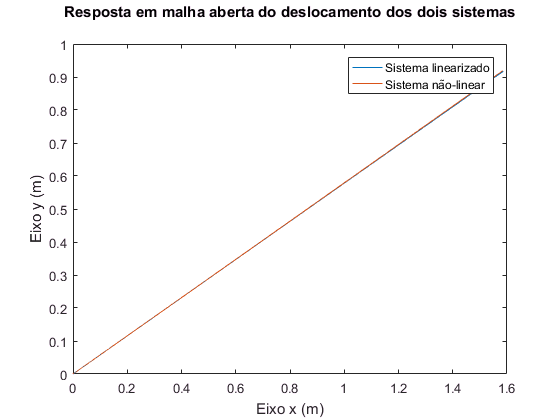

fx = 2.5e5;
fy = 2.5e5;
mz = 0;

[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i);

(4)$F_x = 2.5 \cdot 10^5 N \; ; F_y=2.5 \cdot 10^5 N \; ; M_z=10^7 N.m $

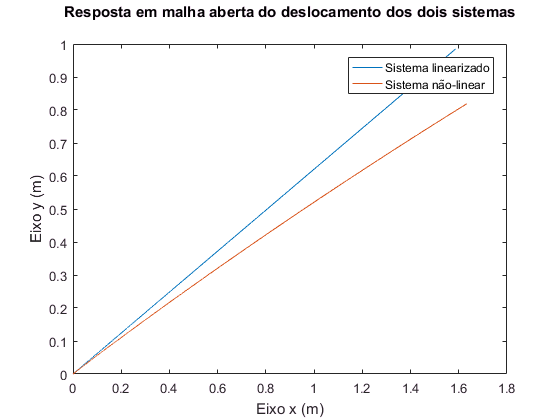

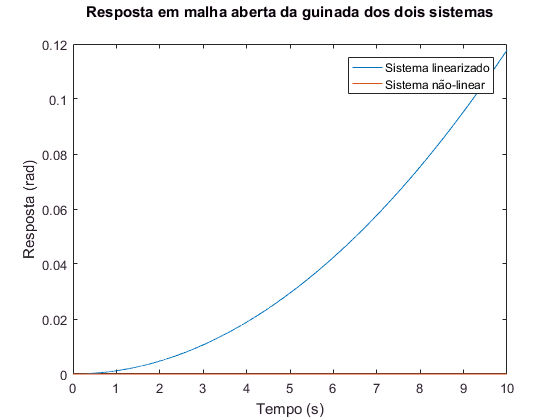

fx = 2.5e5;
fy = 2.5e5;
mz = 1e7;

[xg_linear, yg_linear, psi_linear] = sim_linear(t);
[xg_non_linear, yg_non_linear, psi_non_linear] = sim_non_linear(t);

i=plota_graficos(psi_linear, yg_non_linear, xg_non_linear, xg_linear, yg_linear, psi_non_linear,i);